# Learning and Estimation of Dynamical Systems - Project July 25, 2024

`Student:` **Nicholas Gioia**

`Id:` **0001146569**

## **0. Initialization**

clear all
close all
addpath /Users/nicholas_gioia/Documents/MATLAB/Gioia_Nicholas/Functions/

Student = 'Nicholas Gioia';
Matriculation = '0001146569';

# Exercise 1: Estimation Problem

## 1. Understand the model structure

N = 10000;

[Measurements] = IdentifyThis(N, Student, Matriculation);

u = Measurements.u;
y = Measurements.y;

Therefore we can see the plot of input and output:

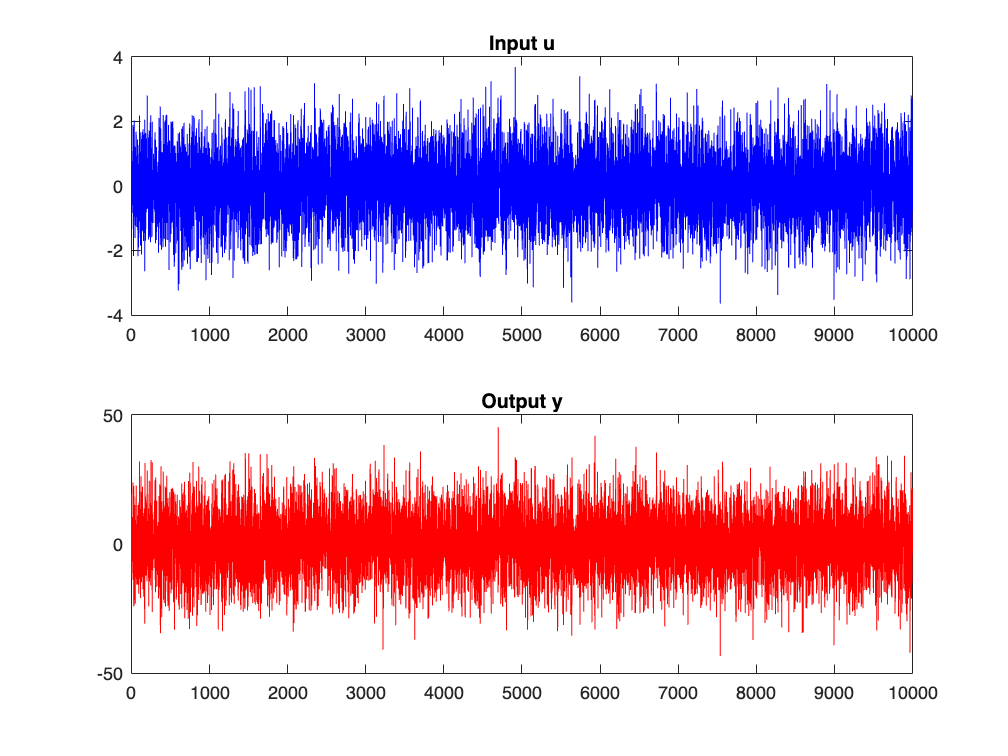

figure
hold on
subplot (2,1,1)
plot(u,'b')
title("Input u")
subplot(2,1,2)
plot(y,'r')
title("Output y")
hold off

In this case, the signals refer to either an ARX or a FIR model. To understand the nature of the model, we have to apply the identification and validation procedure twice for each model. Only then can we fully comprehend the model structure.

## 2. Define the required estimation algorithm

### 2.1 ARX models

The ARX model has the following form:


$$y(t) + a_1y(t-1) + \cdots + a_ny(t-n) = b_1u(t-1) + \cdots + b_nu(t-n) + e(t) $$


In Linear Regression form:


$$y(t)=\varphi(t)^T \theta + \epsilon(t)$$


where:


$$\varphi(t)=[-y(t-1)\cdots-y(t-n) \space u(t-1) \dots u(t-n)]^T$$



$$\theta = [a_1 \cdots a_n \space b_1 \cdots b_n]^T$$


By defining the Hankel Matrix $H(n)$:


$$H(n)=\left[ -H_y(n) \space H_u(n)\right]=$$

$$\left\lbrack \begin{array}{cccccc}
-y\left(0\right) & \ldotp \ldotp \ldotp  & -y\left(1-n\right) & u\left(0\right) & \ldotp \ldotp \ldotp  & u\left(1-n\right)\\
-y\left(1\right) & \ldotp \ldotp \ldotp  & -y\left(2-n\right) & u\left(1\right) & \ldotp \ldotp \ldotp  & u\left(2-n\right)\\
\vdots  & \ddots  & \vdots  & \vdots  & \ddots  & \vdots \\
-y\left(N\right) & \ldotp \ldotp \ldotp  & -y\left(N-n\right) & u\left(N\right) & \cdots  & u\left(N-n\right)
\end{array}\right\rbrack$$


The Hankel matrix organizes the previous samples into a structured form that is useful for identifying the parameters. So, we can write the problem in the form:


$$Y=H(n)\theta + \epsilon$$


Considering the Least Squares Method, once an estimate is available, we can compute the misfit between $y(t)
$ and its estimate $\hat y(t)$, that is:


$$\epsilon(t) = y(t) - \hat y(t)$$


The estimate $\hat \theta$ is such that the following cost function is minimized:


$$J(\theta) = \frac{1}{N} \sum_{t=1}^N\epsilon^2(t) = \frac{1}{N} \sum_{t=1}^N ( y(t) - \varphi^T(t) \theta)^2$$


We can obtain the value of the sulution as:


$$\hat \theta =\left(\frac{H^T H}{N}\right)^{-1}  \frac{ H^TY}{N}   $$


It is convenient to divide the dataset into two parts, a training set and a validation set. The first used for learning the data i.e. used for computing the estimate $\hat \theta$. The second used for evaluating the predictive capabilities of the models obtained with the training set in order to estimate the model complexity. I choose to use the 60% of the dataset for the training set and the remaining 40% for the validation set.

trainingSet.y = y(1:0.6*N);
validationSet.y = y(0.6*N+1:end);
trainingSet.u = u(1:0.6*N);
validationSet.u = u(0.6*N+1:end);

I have defined the follow functions, whose have as input the type of the model:

-  `myHank.m` `->` to compute the Hankel matrix for the ARX model

- LS.m `->` to compute the estimate $\hat \theta$

- costFunc.m `->`  to compute the cost function $J(\hat \theta)$

n = 20;
Hankel_ARX = myHank(trainingSet.u,trainingSet.y,n,'ARX');
thetaHat_ARX = LS(trainingSet.u,trainingSet.y,n,'ARX');

if rank(Hankel_ARX) == 2*n
    disp("The hankel Matrix is full rank")
end

The hankel Matrix is full rank


Now, we can try to use the minimization of the cost function over the training set to estimate the model order:

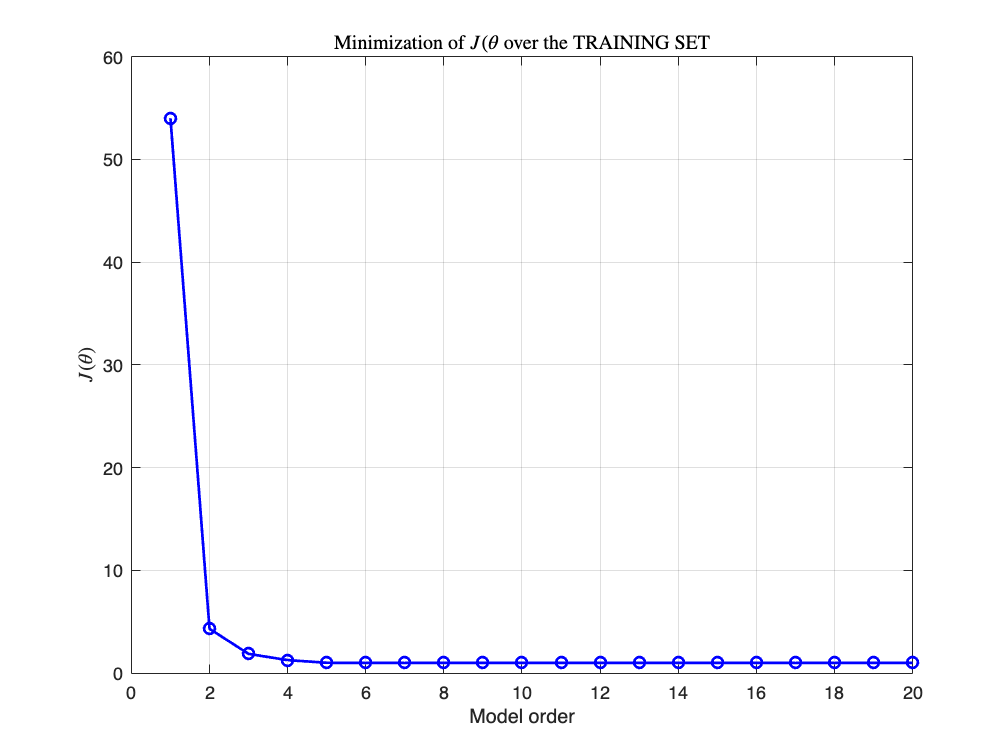

n = 1:20;
J_theta = zeros(length(n),1);

for i=1:length(n)
    thetaHat_ARX = LS(trainingSet.u,trainingSet.y,i,'ARX');
    H = myHank(trainingSet.u,trainingSet.y,i,'ARX');
    J_theta(i) = costFunc(trainingSet.y,thetaHat_ARX,H,'ARX');
end

[min_J_theta, min_n] = min(J_theta);

figure()
plot(n,J_theta, "b-o", "LineWidth",1.5)
title("Minimization of $J(\theta$ over the TRAINING SET", "Interpreter","latex")
xlabel("Model order")
ylabel("$J(\theta)$","Interpreter","latex")
grid on

We can see that the value of the cost function keeps decreasing as the model order increases. The minimum value of $J(\theta)$ gives the following model order:

fprintf("min(J_theta) = %3f and model order = %3f", min_J_theta, min_n)

min(J_theta) = 0.996570 and model order = 20.000000

### 2.2 FIR models

The FIR model has the following form:


$$y(t) = b_1u(t-1) + \cdots + b_nu(t-n) + e(t) $$


In Linear Regression form:


$$y(t)=\varphi(t)^T \theta + \epsilon(t)$$


where:


$$\varphi(t)=[u(t-1) \dots u(t-n)]^T$$



$$\theta = [b_1 \cdots b_n]^T$$


In this case the Hankel Matrix $H_u(n)$ is:


$$H(n)=\left[H_u(n)\right]=$$

$$\left\lbrack \begin{array}{cccc}
u\left(0\right) & u\left(-1\right) & \ldotp \ldotp \ldotp  & u\left(1-n\right)\\
u\left(1\right) & u\left(0\right) & \ldotp \ldotp \ldotp  & u\left(2-n\right)\\
\vdots  & \vdots  & \ddots  & \vdots \\
u\left(N\right) & u\left(N-2\right) & \cdots  & u\left(N-n\right)
\end{array}\right\rbrack$$


We can obtain the value of the sulution as:


$$\hat \theta = (H^T H)^{-1} H^TY$$


I can use the previous functions but as model input 'FIR':

-  `myHank.m` `->` to compute the Hankel matrix for the FIR model

- LS.m `->` to compute the estimate $\hat \theta$

- costFunc.m `->`  to compute the cost function $J(\hat \theta)$

n = 20;
Hankel_FIR = myHank(trainingSet.u,trainingSet.y,n,'FIR');
thetaHat_FIR = LS(trainingSet.u,trainingSet.y,n,'FIR');

if rank(Hankel_FIR) == n
    disp("The hankel Matrix is full rank")
end

The hankel Matrix is full rank


Now, we can try to use the minimization of the cost function over the training set to estimate the model order:

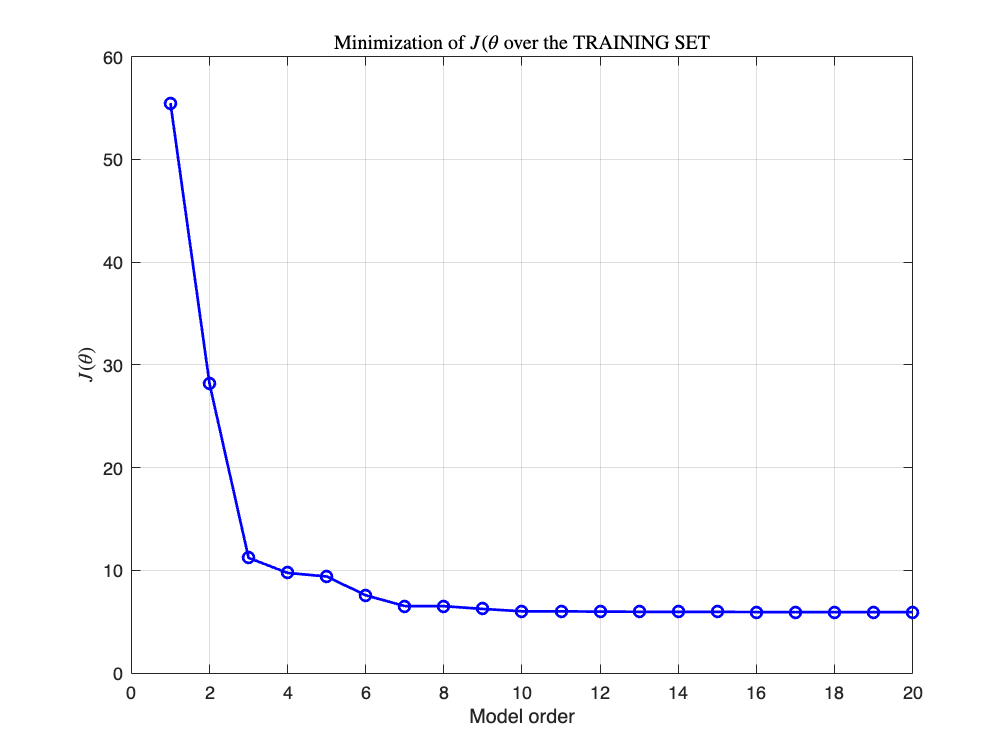

n = 1:20;
J_theta = zeros(length(n),1);

for i=1:length(n)
    thetaHat_FIR = LS(trainingSet.u,trainingSet.y,i,'FIR');
    H = myHank(trainingSet.u,trainingSet.y,i,'FIR');
    J_theta(i) = costFunc(trainingSet.y,thetaHat_FIR,H,'FIR');
end

[min_J_theta, min_n] = min(J_theta);

figure()
plot(n,J_theta, "b-o", "LineWidth",1.5)
title("Minimization of $J(\theta$ over the TRAINING SET", "Interpreter","latex")
xlabel("Model order")
ylabel("$J(\theta)$","Interpreter","latex")
grid on

We can see that the value of the cost function keeps decreasing as the model order increases. The minimum value of $J(\theta)$ gives the following model order:

fprintf("min(J_theta) = %3f and model order = %3f", min_J_theta, min_n)

min(J_theta) = 5.952992 and model order = 17.000000

## 3. Model Estimation

The model complexity selection consists in estimate the hyperparameter $p$ which identifies the dimension of the parameters vector $\theta$. The intended use of the model should be taken into account and another thing to remember is to avoid overfitting and underfitting.

The first method that I can use to evaluate the model order is to use the minimization of the cost function $J(\hat \theta)$, but I already know that I will have the overfitting problem if I try to estimate the model order in the same dataset in which I have estimated the parameters vector. This can be verified, with the assumption that an estimate of $\hat \theta$ is available we need to compute it. 

From the previous section, I have estimated a model order of 17 for both the ARX and FIR models.

It is preferrable to use methods able to validate the model order directly on the training set.

### Final Prediction Error (FPE)

To use this method we have to consider the criterion function:

$FPE=\frac{N+p}{N-p}J(\hat{\theta}_N) \simeq J(\hat{\theta}_N) + \frac{2p}{N}J(\hat{\theta}_N)$ if $N \to \infty$

We known that for $N \to \infty$ the FPE belongs to the criteria with complexity terms, whose are criteria that in some ways penalize the decrease of the cost function with increasing orders. 

#### Final Prediction Error - ARX model

I have define two functions, whose have as input the type of the model:

- `FPE_base.m -> `which considers the formula without the assumption

- `FPE_ass.m -> `which considers the formula with the assumption

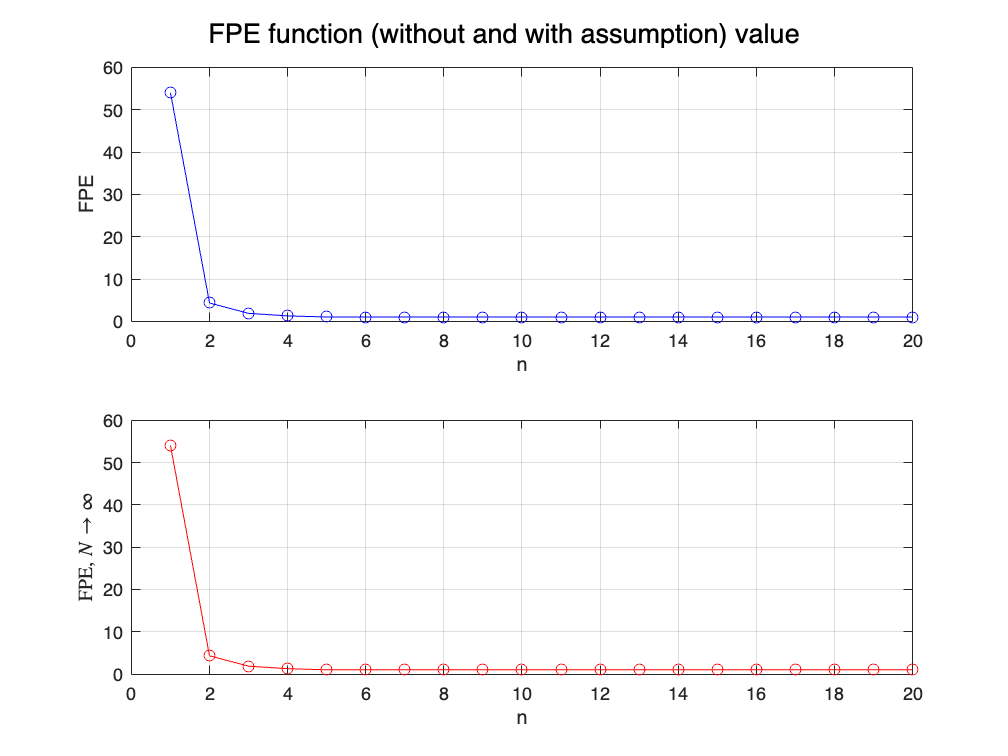

n = 1:20;

FPE_1 = zeros(length(n),1); % initialization for the FPE without assumption
FPE_2 = zeros(length(n),1); % initialization for the FPE with assumption

for i=1:length(n)
    theta_order = LS(trainingSet.u,trainingSet.y,i,'ARX');
    FPE_1(i) = FPE_base(trainingSet.u,trainingSet.y,theta_order,'ARX');
    FPE_2(i) = FPE_ass(trainingSet.u,trainingSet.y,theta_order,'ARX');
end

[minFPE_base, min_n_FPE_base] = min(FPE_1);
[minFPE_ass, min_n_FPE_ass] = min(FPE_2);

figure()
sgtitle("FPE function (without and with assumption) value")
subplot(2,1,1)
plot(n,FPE_1,"b-o")
ylabel("FPE")
xlabel("n")
grid on
subplot(2,1,2)
plot(n,FPE_2,'r-o')
xlabel("n")
ylabel("FPE, $N\to\infty$","Interpreter","latex")
grid on

fprintf("The FPE without the assumption estimate a model order of: %3f",min_n_FPE_base)

The FPE without the assumption estimate a model order of: 6.000000

fprintf("The FPE with the assumption estimate a model order of: %3f",min_n_FPE_ass)

The FPE with the assumption estimate a model order of: 6.000000

The two FPE gives back the same model order. We can use other 2 methods based on the criteria with complexity terms to confirm this result.

#### Final Prediction Error - FIR model

Also in this case I can use the previous functions but as model input 'FIR':

- `FPE_base.m -> `which considers the formula without the assumption

- `FPE_ass.m -> `which considers the formula with the assumption

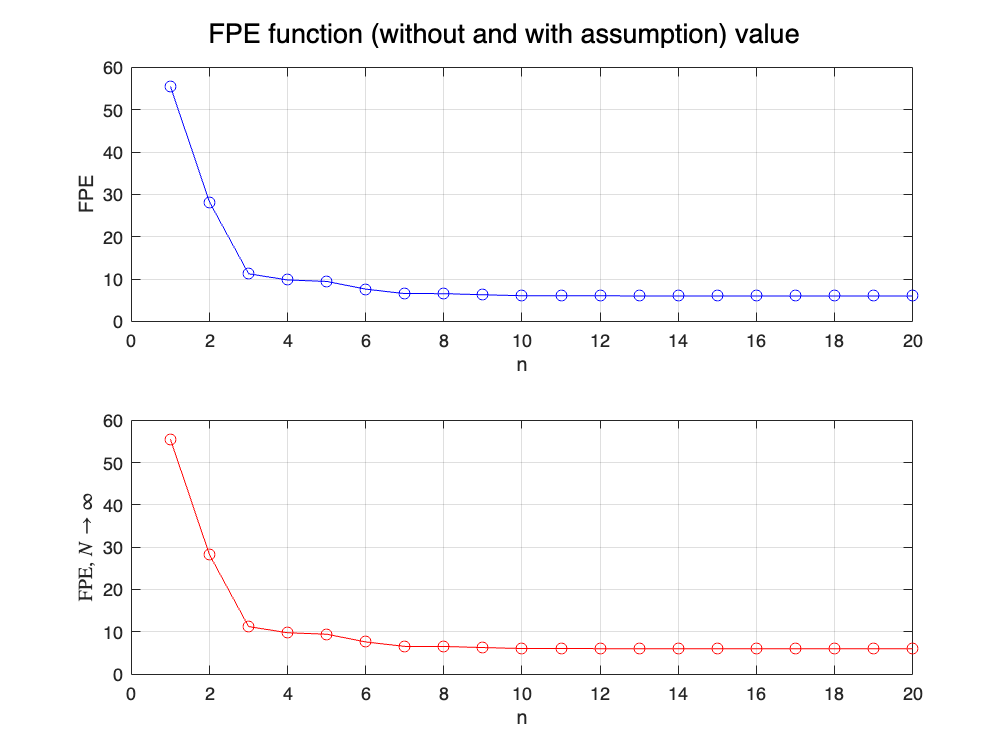

n = 1:20;

FPE_1 = zeros(length(n),1); % initialization for the FPE without assumption
FPE_2 = zeros(length(n),1); % initialization for the FPE with assumption

for i=1:length(n)
    theta_order = LS(trainingSet.u,trainingSet.y,i,'FIR');
    FPE_1(i) = FPE_base(trainingSet.u,trainingSet.y,theta_order,'FIR');
    FPE_2(i) = FPE_ass(trainingSet.u,trainingSet.y,theta_order,'FIR');
end

[minFPE_base, min_n_FPE_base] = min(FPE_1);
[minFPE_ass, min_n_FPE_ass] = min(FPE_2);

figure()
sgtitle("FPE function (without and with assumption) value")
subplot(2,1,1)
plot(n,FPE_1,"b-o")
ylabel("FPE")
xlabel("n")
grid on
subplot(2,1,2)
plot(n,FPE_2,'r-o')
xlabel("n")
ylabel("FPE, $N\to\infty$","Interpreter","latex")
grid on

fprintf("The FPE without the assumption estimate a model order of: %3f",min_n_FPE_base)

The FPE without the assumption estimate a model order of: 16.000000

fprintf("The FPE with the assumption estimate a model order of: %3f",min_n_FPE_ass)

The FPE with the assumption estimate a model order of: 16.000000

The two FPE gives back the same model order. We can use other 2 methods based on the criteria with complexity terms to confirm this result.

### Akaike Information Criterion (AIC)

The criterion function in this case is:


$$AIC = N \log J(\hat \theta_N) + 2p$$


AIC and FPE are asymptotically equivalent. However, both the method are considered not consistent, in the sense that the convergence of the two criteria to the true order is not guaranteed even if the samples number is very large. 

#### Akaike Information Criterion - ARX model

The function is implemented in the follow function, with model input 'ARX':

- `AIC.m`

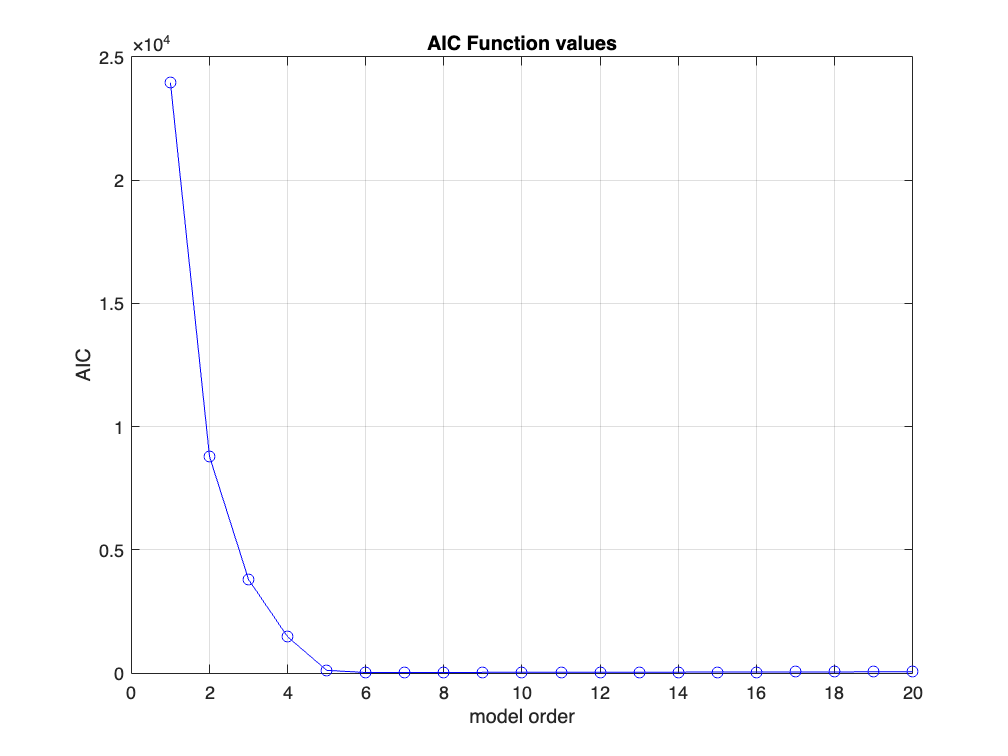

n = 1:20;
AIC_try = zeros(length(n),1); % initialization of the value of AIC function

for i=1:length(n)
    theta_try = LS(trainingSet.u,trainingSet.y,i,'ARX');
    AIC_try(i) = AIC(trainingSet.u,trainingSet.y,theta_try,'ARX');
end

[min_AIC, min_n_AIC] = min(AIC_try);
figure()
plot(n,AIC_try,'b-o')
ylabel("AIC")
xlabel("model order")
grid on
title("AIC Function values")

fprintf("The model complexity estimated by AIC is: %3f",min_n_AIC)

The model complexity estimated by AIC is: 6.000000

Even the AIC gives the same model complexity for the ARX model.

#### Akaike Information Criterion - FIR model

The function is implemented in the follow function, with model input 'FIR':

- `AIC.m`

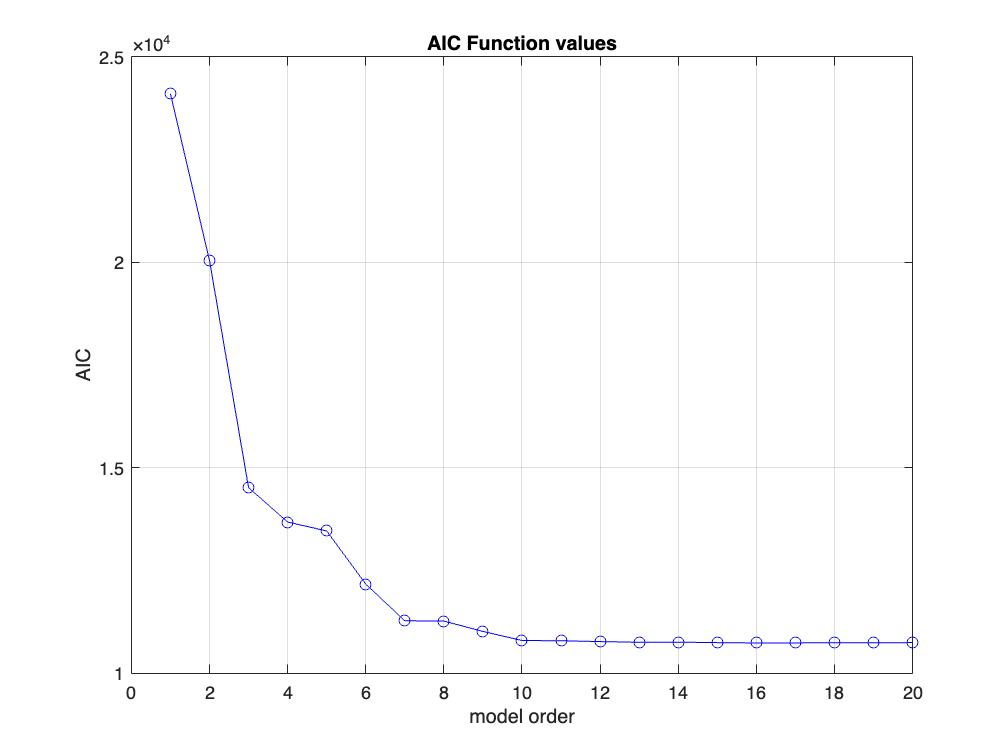

n = 1:20;
AIC_try = zeros(length(n),1); % initialization of the value of AIC function

for i=1:length(n)
    theta_try = LS(trainingSet.u,trainingSet.y,i,'FIR');
    AIC_try(i) = AIC(trainingSet.u,trainingSet.y,theta_try,'FIR');
end

[min_AIC, min_n_AIC] = min(AIC_try);
figure()
plot(n,AIC_try,'b-o')
ylabel("AIC")
xlabel("model order")
grid on
title("AIC Function values")

fprintf("The model complexity estimated by AIC is: %3f",min_n_AIC)

The model complexity estimated by AIC is: 16.000000

Even the AIC gives the same model complexity for a FIR model.

I still want to try the last criterion to confirm the result.

### Minimum Description Lenght Criterion (MDL)

It is the only one that converges to the true order of the model. It is based on the function:


$$MDL = N \log J(\hat \theta_N) + p \log N$$


#### Minimum Description Lenght Criterion - ARX

The function is implemented in the follow function, with model input 'ARX':

- `MDL.m `

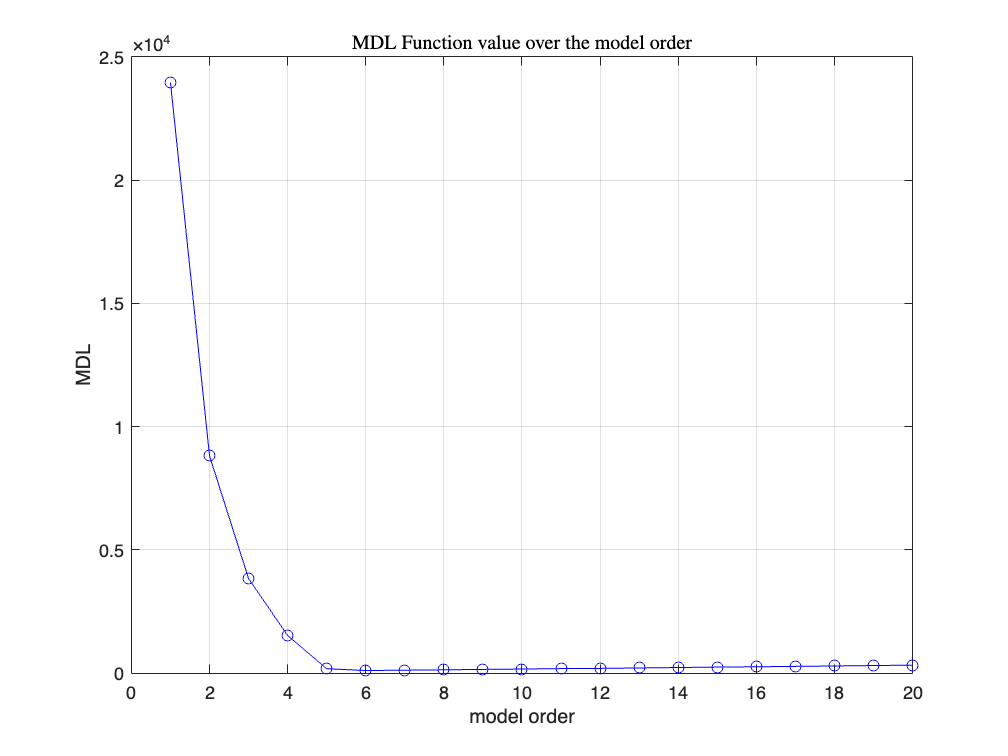

n = 1:20;

MDL_try = zeros(length(n),1); % initialization of the value of MDL function

for i=1:length(n)
    theta_try = LS(trainingSet.u,trainingSet.y,i,'ARX');
    MDL_try(i) = MDL(trainingSet.u,trainingSet.y,theta_try,'ARX');
end
[min_MDL, min_n_MDL] = min(MDL_try);

figure()
plot(n,MDL_try,'b-o')
ylabel("MDL")
xlabel("model order")
title("MDL Function value over the model order","Interpreter","latex")
grid on

In this case we have that:

fprintf("The estimated order by the MDL is: %3f", min_n_MDL)

The estimated order by the MDL is: 6.000000

The order of our model is $p_{ARX} = 6$

p_ARX = 6;
Hankel_ARX = myHank(trainingSet.u,trainingSet.y,p_ARX,'ARX');
thetaHat_ARX = LS(trainingSet.u,trainingSet.y,p_ARX,'ARX');

#### Minimum Description Lenght Criterion - FIR

The function is implemented in the follow function, with model input 'FIR':

- `MDL.m `

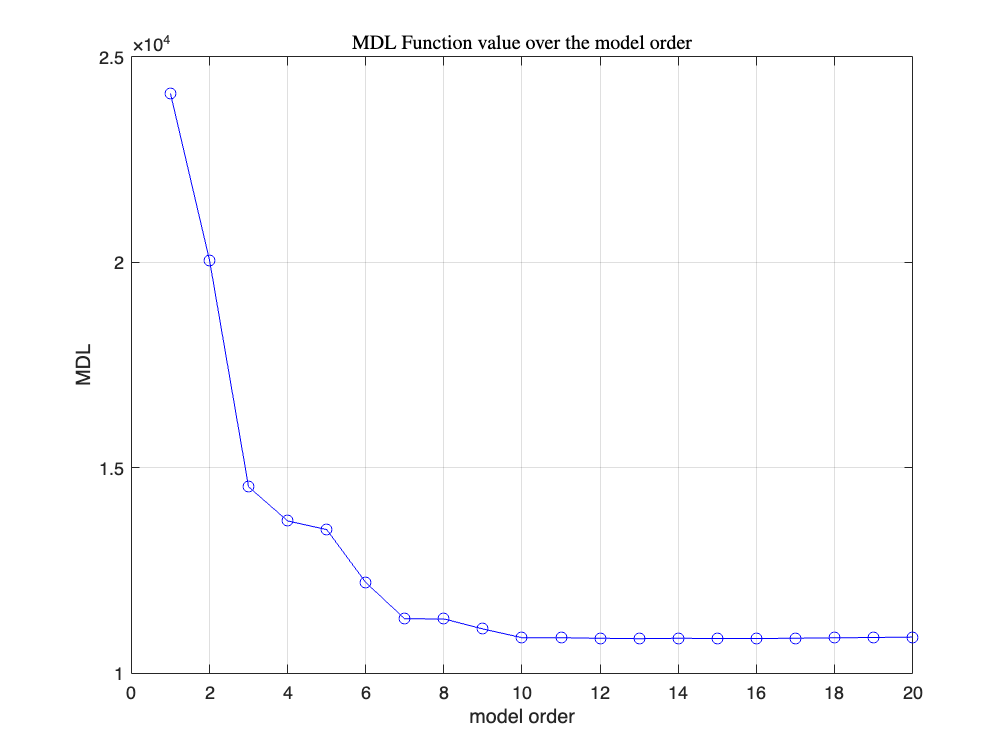

n = 1:20;

MDL_try = zeros(length(n),1); % initialization of the value of MDL function

for i=1:length(n)
    theta_try = LS(trainingSet.u,trainingSet.y,i,'FIR');
    MDL_try(i) = MDL(trainingSet.u,trainingSet.y,theta_try,'FIR');
end
[min_MDL, min_n_MDL] = min(MDL_try);

figure()
plot(n,MDL_try,'b-o')
ylabel("MDL")
xlabel("model order")
title("MDL Function value over the model order","Interpreter","latex")
grid on

In this case we have that:

fprintf("The estimated order by the MDL is: %3f", min_n_MDL)

The estimated order by the MDL is: 13.000000

The order of our model is $p_{ARX} = 13$

p_FIR = 13;
Hankel_FIR = myHank(trainingSet.u,trainingSet.y,p_FIR,'FIR');
thetaHat_FIR = LS(trainingSet.u,trainingSet.y,p_FIR,'FIR');

### 4. Model Validation

Once we have chosen the model order and estimated the parameters vector, we have to evaluate the capability of the model too describe the real process that generates the initial dataset.

In order to do that, there are two assumptions that we have to verify:

- $\epsilon(t,\hat \theta_N)$ is a zero-mean white process

- $\epsilon(t,\hat \theta_N)$ is uncorrelated with the input $u(t)$

To verify them, I will perform two tests on residuals:

- whiteness test

- cross-correlation test

#### Whiteness Test

Consider the sequence of residuals: $\epsilon(1,\hat\theta_N),\dots,\epsilon(N,\hat\theta_N)$, we can perform the following statistical hypothesis test:


$$\left\lbrace \begin{array}{ll}
H_0 :\epsilon \left(t,\hat{\theta_N } \right) \\
H_1 :\mathrm{not}\;H_0  
\end{array}\right.$$


We can consider two version of the test, the $\chi^2(m)$ based and the Gaussian test based.

 The $\chi^2$ test is defined as follows:


$$\left\lbrace \begin{array}{ll}
H_0: x \le \chi^2_{\alpha}(m) \\
H_1: x \gt \chi^2_{\alpha}(m)
\end{array}$$


where the test quantity $x$ is:


$$x = N\frac{\hat{r}^T_{\epsilon}\hat{r}_{\epsilon}}{\hat{r}^2_{\epsilon}(0)}$$


The $\chi^2$ Test is implemented in the function: 

- `wtest_chi.m ` 

The Gaussian test is defined as follows:

$\sqrt{N}\hat\gamma(\tau) \sim \mathcal{N}(0,1)$ as $N \to \infty$ and $\tau = 1,\dots,m$

where:


$$\hat\gamma(\tau) = \frac{\hat{r}_{\epsilon}(\tau)}{\hat{r}_{\epsilon}(0)}$$
       
$$\tau = 1,\dots,m$$


is the normalized autocorrelation function. 

The Gaussian Test is defined as:

$\left\lbrace \begin{array}{ll}
H_0^{\tau}: \vert\frac{\hat\gamma(\tau)}{\sqrt{N}}\vert \leq z \\
H_1^{\tau} : \vert\frac{\hat\gamma(\tau)}{\sqrt{N}}\vert \gt z
  
\end{array}\right.$     where $\tau = 1, \dots ,m$ 

and $z$ is computed from the Normal Distribution table remembering that $P(x\leq{z}) = 1 - \frac{\alpha}{2}$.

The Whiteness Gaussian Test is implemented in the function:

- `wtest_gaussian.m`

We should also have computed the vector of residual upon which we will try the test. It is necessary to compute the residuals of the validation set (to test its predictive capabilities). To do that I have defined the function:

- `residuals.m`

epsilon_validation_ARX = residuals(validationSet.u,validationSet.y,thetaHat_ARX,'ARX');
epsilon_validation_FIR = residuals(validationSet.u,validationSet.y,thetaHat_FIR,'FIR');


We can now apply the tests:

% chi test ARX
significance_level = 0.05;
m = 50;

whitenes_chi_square = wtest_chi(epsilon_validation_ARX,m,significance_level);
if whitenes_chi_square == 1
    disp("Chi_square Whiteness test for ARX model Passed !")
else
    disp("Chi_square Whiteness test for ARX model Failed !")
end

Chi_square Whiteness test for ARX model Passed !



% gaussian test ARX
whiteness_gauss = wtest_gauss(epsilon_validation_ARX,m,significance_level);
if whiteness_gauss == 1
    disp("Gaussian Whiteness test for ARX model Passed !")
else
    disp("Gaussian Whiteness test for ARX model Failed !")
end

Gaussian Whiteness test for ARX model Failed !



% chi test FIR
whitenes_chi_square = wtest_chi(epsilon_validation_FIR,m,significance_level);
if whitenes_chi_square == 1
    disp("Chi_square Whiteness test for FIR model Passed !")
else
    disp("Chi_square Whiteness test for FIR model Failed !")
end

Chi_square Whiteness test for FIR model Failed !



% gaussian test FIR
whiteness_gauss = wtest_gauss(epsilon_validation_FIR,m,significance_level);
if whiteness_gauss == 1
    disp("Gaussian Whiteness test for FIR model Passed !")
else
    disp("Gaussian Whiteness test for FIR model Failed !")
end

Gaussian Whiteness test for FIR model Failed !


It is not necessary that both tests are passed to claim that the residuals are whiteness, we need at least one of them. 

#### Cross-Correlation Test

The hypothesis test is defined as:


$$\left\lbrace \begin{array}{ll}
H_0 :\epsilon \left(t,\hat{\theta_N } \right)\ and \ u(t)\ \mathbf{uncorrelated} \\
H_1 :\mathrm{not}\;H_0  
\end{array}\right.$$


considering the vector of sample cross correlation:

$\hat{r}_{\epsilon{u}} = \left[ \begin{array}{ll}
\hat{r}_{\epsilon{u}}(\overline\tau+1) \\
\hat{r}_{\epsilon{u}}(\overline\tau+2) \\
\vdots \\
\hat{r}_{\epsilon{u}}(\overline\tau+m)
\end{array} \right]$ where $\overline\tau \ge n$

Also in this case, it is possible to apply the $\chi^2$ or the Gaussian Test. The two test quantities are:

- for the $\chi^2$: $x = N\frac{\hat{r}_{\epsilon u}^T\hat{\Sigma}_u^{-1}\hat{r}_{\epsilon u}}{\hat{r}_{\epsilon}(0)}$

- for the Gaussian: $\hat\gamma(\tau) = \frac{\hat{r}_{\epsilon{u}}(\tau)}{\sqrt{\hat{r}_{\epsilon}(0)\hat{r}_u(0)}}$

where $\hat\Sigma_u = \frac{1}{N}\sum\varphi_u(t)\varphi^T_u(t)$ is he sample autocovariance matrix and $r_{\epsilon u}$ the autocorrelation function between the residuals and the input.

The test are implemented in the functions:

- `crosscorr_chi.m`

- `crosscorr_gaussian.m`

% chi test ARX
cross_chi = cross_corr_chi(epsilon_validation_ARX,validationSet.u,m,significance_level,p_ARX);
if cross_chi == 1
    disp("Chi_square Cross-correlation test for ARX model Passed !")
else
    disp("Chi_square Cross-correlation test for ARX model Failed !")
end

Chi_square Cross-correlation test for ARX model Passed !


% gaussian test ARX
cross_gauss = cross_corr_gauss(epsilon_validation_ARX,validationSet.u,m,significance_level,p_ARX);
if cross_gauss == 1
    disp("Chi_square Cross-correlation test for ARX model Passed !")
else
    disp("Chi_square Cross-correlation test for ARX model Failed !")
end

Chi_square Cross-correlation test for ARX model Passed !


% chi test FIR
cross_chi = cross_corr_chi(epsilon_validation_FIR,validationSet.u,m,significance_level,p_FIR);
if cross_chi == 1
    disp("Chi_square Cross-correlation test for FIR model Passed !")
else
    disp("Chi_square Cross-correlation test for FIR model Failed !")
end

Chi_square Cross-correlation test for FIR model Passed !


% gaussian test FIR
cross_gauss = cross_corr_gauss(epsilon_validation_FIR,validationSet.u,m,significance_level,p_FIR);
if cross_gauss == 1
    disp("Chi_square Cross-correlation test for FIR model Passed !")
else
    disp("Chi_square Cross-correlation test for FIR model Failed !")
end

Chi_square Cross-correlation test for FIR model Passed !


It is not necessary that both tests are passed to claim that input and residuals are uncorrelated, we need at least one of them. 

#### Conclusion

The ARX model passes both the whiteness and cross-correlation tests, the FIR model fails the whiteness tests, it generally means:

- The ARX model is likely a good representation of the system since it passes the validation tests.

- The residuals of the ARX model are white noise and uncorrelated with the input, indicating that the model has captured the relevant dynamics of the system.

- The residuals from the FIR model are not white noise, suggesting that the FIR model may be missing important aspects of the system's behavior.

Therefore it is reasonable to consider the ARX model as the validated and preferable model, the FIR model may not be an adequate representation of the system.

To see how good the model estimated is in representing the data, I will plot the the prediction $\hat{y}(t) = \varphi(t)^T\hat{\theta}$ by using the validation set comparing it with $y(t)$. For a good model, $\hat{y}(t)$ should resemble the measured output $y(t)$. Let's see:

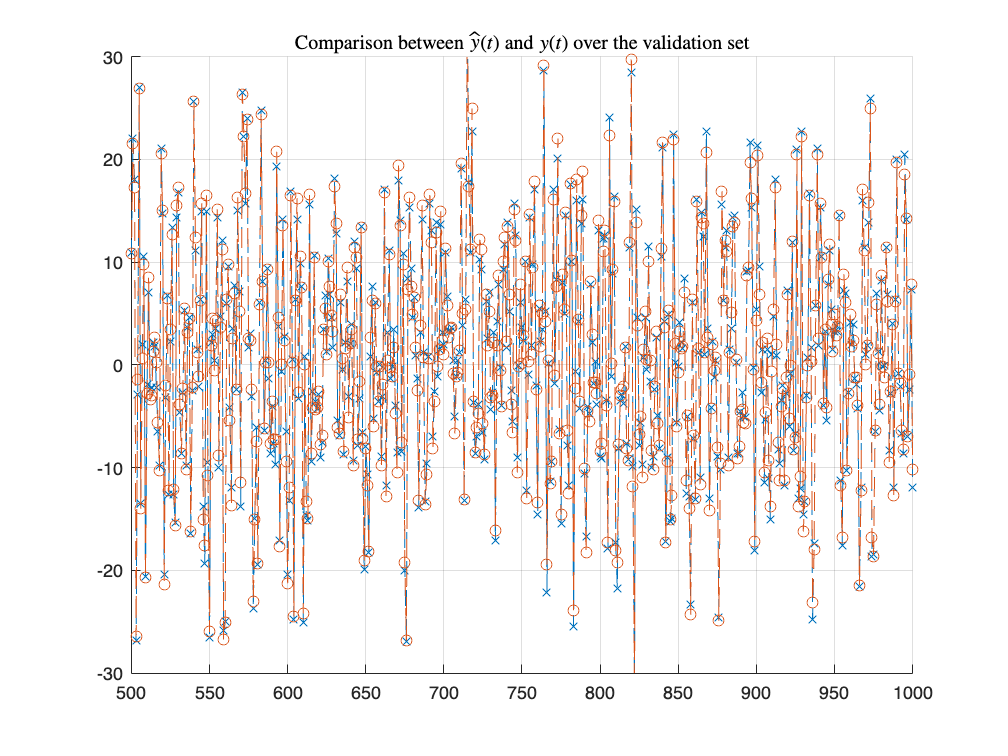

n = p_ARX;
H = myHank(validationSet.u,validationSet.y,n,'ARX');

figure()
hold on
title("Comparison between $\hat{y}(t)$ and $y(t)$ over the validation set","Interpreter","latex")
plot(validationSet.y(n+1:end),'--x')
plot(H*thetaHat_ARX,'--o')
hold off
grid on, zoom on
xlim([500 1000])
ylim([-30 30])

# Exercise 2: Classification Problem

## 0. Initialization

Student = 'Nicholas Gioia';
Matriculation = '0001146569';

N = 5000;

[FeatureSet] = ClassifyThose(N,Student,Matriculation);

Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;

## 1. Feature set

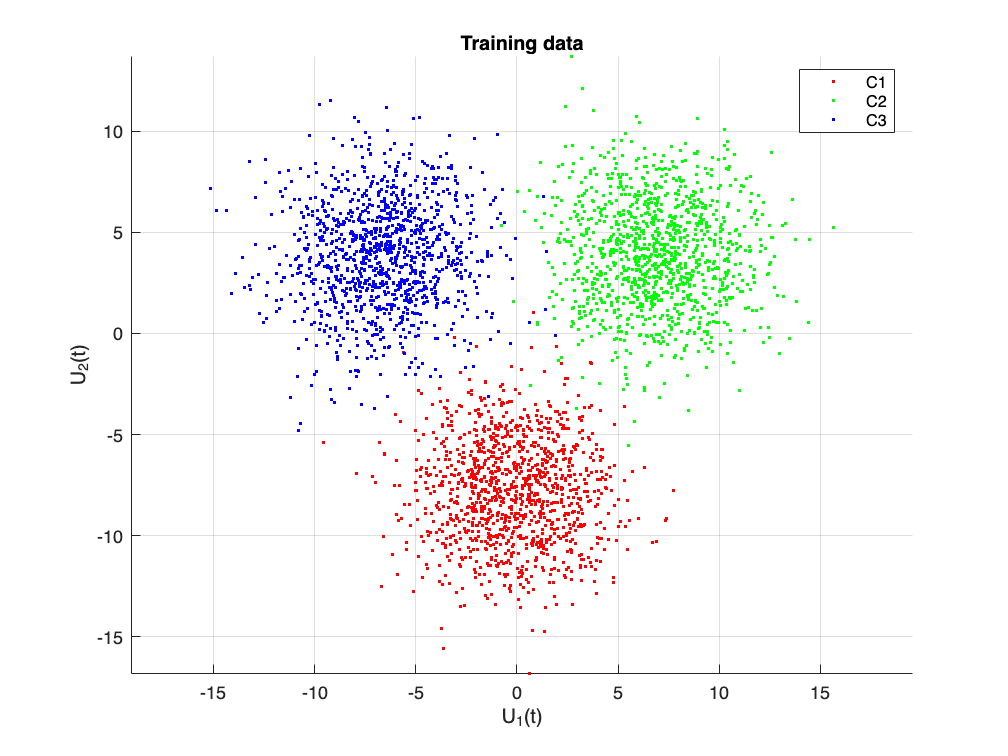

N_train = size(Utrain, 1);
dimension = size(Utrain, 2);
N_test = size(Utest, 1);

figure();
hold on
grid on
gscatter(Utrain(:,1), Utrain(:,2), Ytrain, 'rgb', '.');
title('Training data');
xlabel("U_1(t)");
ylabel("U_2(t)");
legend({'C1','C2','C3'});
axis equal

From the picture we can see that we are in the case of linear boundaries and in a multi-class problem with 3 classes.

We can evaluate the classifier performances by computing the following quantity:

- Error Rate $E_r$: 


$$E_r = \frac{1}{N}\sum_{t=1}^{N}I(y(t),\hat{y}(t))$$
 

            where $I(y(t),\hat{y}(t))$ is the indicator variable $I(y(t),\hat{y}(t)) = \begin{cases} 1 & if\ y(t) \neq \hat{y}(t) \\ 0 & if\ y(t) = \hat{y}(t) \end{cases}$

The problem can be solve with the Bayes Classifier, which assign to each input the most-likely class:


$$C_i = \underset{i}{\arg\max}P(C_i | u(t)) = P(y(t) = y^i | u(t))$$


## 2. Classification Algorithm Definition

The problem in a real data setting is that we do not really know the conditional probabilities, therefore we need to define a method to estimate them to solve the problem, and we make use of the logistic regression.

The Logistic Regression Algorithm is obtained according maximum likelihood estimation. We need a decision boundary, which is in general an hyperplane defined as:

$\beta_{0}+\beta_{1} u_{1}(t)+\beta_{2} u_{2}(t)+\cdots+\beta_{r} u_{r}(t)=0$. 

That can be rewritten in the regression form

$\varphi^{T}(t) \theta=0$ with $\varphi(t)=\left[1 \quad u_{1}(t) \quad u_{2}(t) \quad \cdots \quad u_{r}(t)\right]^{T}
$ and $\theta=\left[\beta_{0} \quad \beta_{1} \quad \cdots \quad \beta_{r}\right]^{T}$ 

In our particular case the boundary is a line in $\mathbb{R}^2$ ($r=2$).

Our goal now is to estimate the parameters of $\theta$ to find the decision boundaries. The regression is based on the so-called sigmoid function $f(z(t))$, it must be such that:


$$f(z(t))\in(0,1)$$



$$f(z(0)) = 0.5$$



$$f(z(t)) > 0.5 \ if\ z(t) > 0$$
 


$$f(z(t)) < 0.5 \ if\ z(t) < 0$$
 

$f(z(t)) \to 1$ if $z(t) \to \infty$ and $f(z(t)) \to 0$ if $z(t) \to -\infty$

The sigmoid function is then defined as:

$f(z)=\frac{e^{z}}{1+e^{z}}=\frac{1}{1+e^{-z}}$  with $z(t)=\varphi^{T}(t) \theta$

I known that:


$$P(C_1|u(t)) = f(z(t))$$



$$P(C_2|u(t)) = 1-f(z(t))$$


where $z(t)$:


$$z(t) = log\frac{P(C_1|u(t))}{P(C_2|u(t))}=log\frac{f(z(t))}{1-f(z(t))}$$


We want to find the estimate that maximize the conditional probability of the obeservation, therefore we can use the maximum likelihood estimation. In particular using the LOG-likelihood function the optimization problem becomes:


$$log(P(Y|\theta)) = \sum_{t=1}^N [y(t)log(f(z(t))) + (1-y(t))log(1-f(z(t)))]$$


Maximize the above function is equivalent to minimize its negative, so we have to find the estimate $\hat \theta$ minimizing:


$$J(\theta) = - \log P(Y|\theta)$$


So, the problem is:


$$\min_{\theta} J(\theta)$$


Since we are dealing with a multiclass problem, we have two alternatives:

- One-vs-all: the multiclass problem is splitted into M two-class problems. The generici i-th binary problem involves the classes $C_i$ and $\overline{C_i}=\left\{C_1, \cdots, C_{i-1},C_{i+1},\cdots,C_M\right\}$. Therefore, $M
$ conditional probabilities $\hat{P}(C_i|u(t)), \space i = 1,2,\cdots,M$ are estimated. A new input $u(t)$ is assigned to the class $C_k$ such that:

 
$$k= \underset{ i \in \left\{1,2,\dots,M\right\}}{\text{arg max}}  \space\hat{P}(C_i|u(t)) $$


- Multiclass logistic regression: the posterior probabilities are modelled by using the normalized exponential:


$$P(C_i|u(t))= \frac{e^{z_i(t)}}{e^{z_1(t)} + e^{z_2(t)} + \cdots + e^{z_M(t)}} \hspace{1cm}   i = 1,2,\cdots,M$$


              where 

            
$$z_i(t) = \varphi^T(t)\theta_i \hspace{1cm}i=1,2,\cdots,M$$


            The input space U = Rr can thus be divided into M regions defined by a set of M hyperplanes. Each hyperplane represents the linear 

            decision boundary between two classes. More precisely, the hyperplane separating classes k and j is described by the equation:


$$(z_k(t) - z_j(t))=0 \space \text{that is} \space \varphi^T(t)(\theta_k - \theta_j) = 0$$


For both methods, the parameter vectors $\theta_1,\theta_2,\dots$ are estimated by using again maximum likelihood and Newton’s method.

I have defined the functions:

- `sigmoid.m` `->` which implements the sigmoid function

- `costFunction_class.m` `->` which implements the cost function

To solve this optimization problem we can use the Newton-Raphson Algorithm:


$$\hat{\theta}^{k+1} = \hat{\theta}^k - \eta^kJ^{''}(\hat{\theta}^k)^{-1}J^{'}(\hat{\theta}^k)^T$$


in particular I choose to use the gradient descent algorithm, so:


$$\hat{\theta}^{k+1} = \hat{\theta}^k - \eta^kJ^{'}(\hat{\theta}^k)$$


where:

$\eta^k$ is the stepsize


$$J^{'}(\theta) = \Phi^T(F(\theta) - Y)$$



$$J^{''}(\theta) = \Phi^TW(\theta)\Phi$$



$$\Phi = \left[\begin{array}{ll}
1 & u_1(1) & \dots & u_r(1) \\
\vdots & u_1(2)  & \dots & u_r(2) \\
\vdots & \vdots & \ddots & \vdots \\
1 & u_1(N) & \dots & u_r(N)


\end{array} \right]$$



$$Y = [y(1)\ \dots \ y(N)]^T$$



$$F(\theta) = [f(z(1))\ \dots \ f(z(N))]^T$$



$$W(\theta) = \left[\begin{array}{ll}
f(z(1))(1-f(z(1)) & \ \ \ \ \ \ \ \ 0 & \dots & \ \ \ \ \ \ \ \ 0 \\
\ \ \ \ \ \ \ \ 0 & f(z(2))(1-f(z(2)) & \dots & \ \ \ \ \ \ \ \ 0 \\
\ \ \ \ \ \ \ \ 0 & \ \ \ \ \ \  \ \ \dots & \dots & f(z(N))(1-f(z(N)) \\
\end{array}\right]$$


I have defined the entire algorithm in the function:

- `oneVsAll_Train.m `

% Set the stepsize, and number of iterations for the cost function
eta = 0.01;
num_iters = 100;
num_labels = numel(unique(Ytrain));

% Train the Logistic Regression models using One-vs-All
theta_star = oneVsAll_Train(Utrain, Ytrain, num_labels, eta, num_iters);

## 3. Classification Algorithm Test

To verify the obtained classificator I have defined the function:

- `oneVsAll_Pred.m -> `computes the prediction

and the function:

- `plotDecisionBoundaries.m -> plot all the decision boundaries and the relative classes`

First, I verify the obtained classificator on the provided training set:

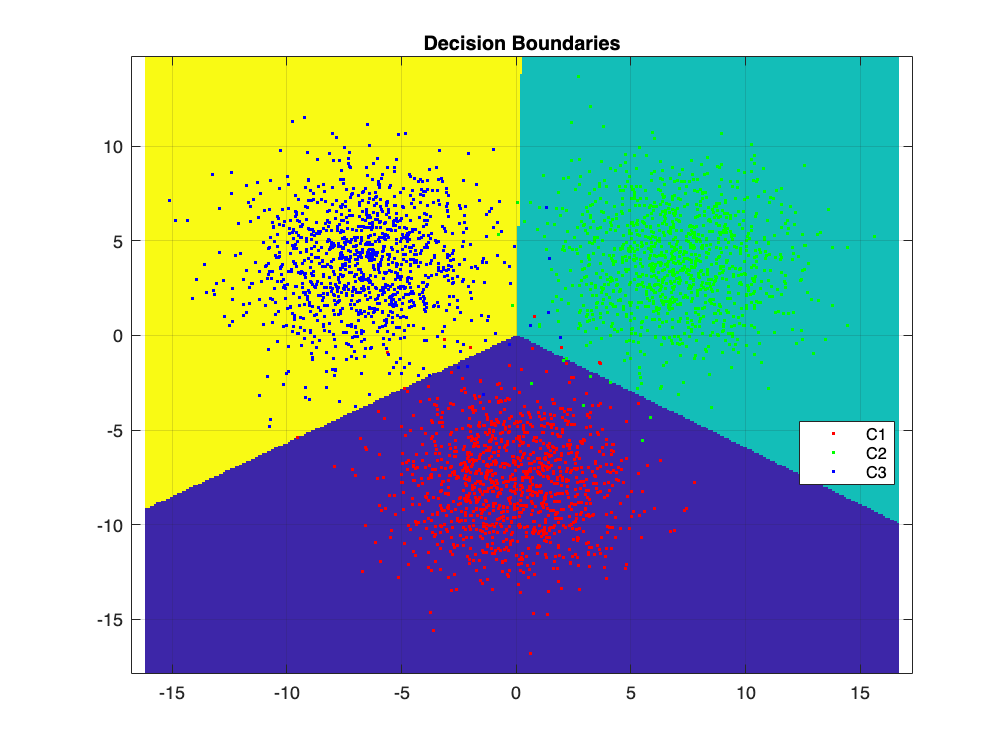

y_pred = oneVsAll_Pred(theta_star, Utrain);
plotDecisionBoundaries(theta_star, Utrain, Ytrain);

To compute the classification error rate I have defined the function:

- `errorRate.m `

error_rate = errorRate(y_pred, Ytrain);
disp(['Error Rate of the classificator on the training set: ', num2str(error_rate * 100), '%']);

Error Rate of the classificator on the training set: 0.77143%


Now I can try to verify my classificator on the test set:

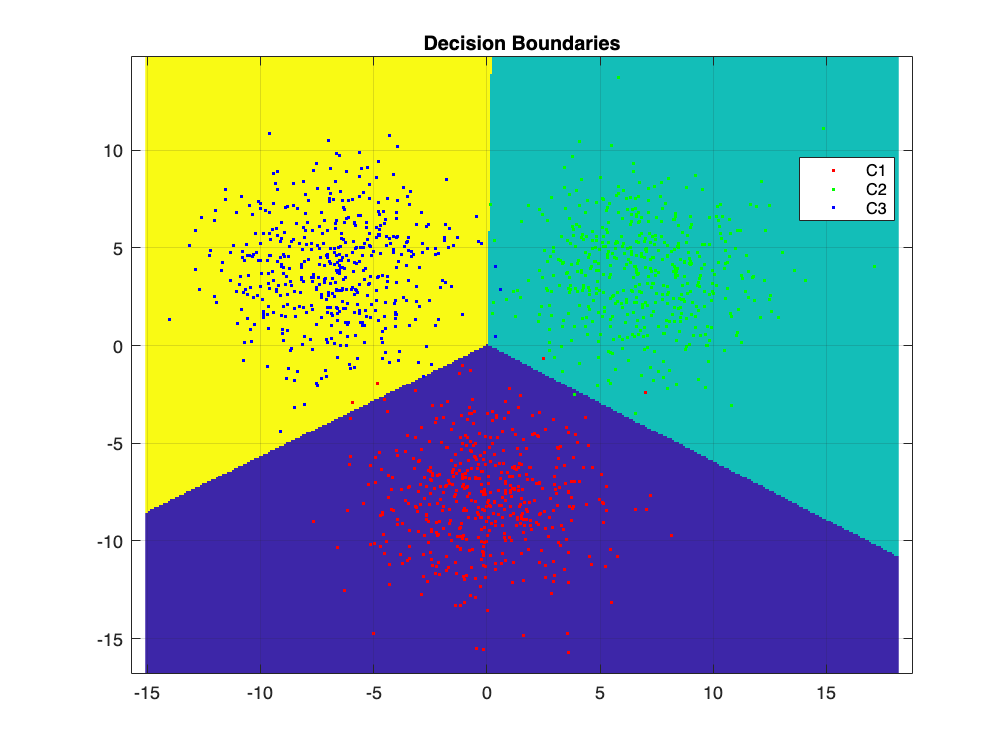

y_pred = oneVsAll_Pred(theta_star, Utest);
plotDecisionBoundaries(theta_star, Utest, Ytest);

error_rate = errorRate(y_pred, Ytest);
disp(['Error Rate of the classificator on the test set: ', num2str(error_rate * 100), '%']);

Error Rate of the classificator on the test set: 0.53333%


We may evaluate the classificator in comparison with `fitcdiscr()` matlab function, based on the linear discriminant analysis:

LDAobj = fitcdiscr(Utrain,Ytrain);
[label,score] = predict(LDAobj,Utrain);

error_rate = errorRate(label, Ytrain);
disp(['Error Rate using fitcdiscr() function on the training set: ', num2str(error_rate * 100), '%']);

Error Rate using fitcdiscr() function on the training set: 0.77143%


[label,score] = predict(LDAobj,Utest);
error_rate = errorRate(label, Ytest);
disp(['Error Rate using fitcdiscr() function on the training set: ', num2str(error_rate * 100), '%']);

Error Rate using fitcdiscr() function on the training set: 0.53333%
